# 4-6-2016 - Multisubject Anova Analysis 

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaMags3 = [];
anovaBetaMags1 = [];
anovaBetaBase = [];
anovaBetaSID = {};
anovaNumStims = {};
anovaTotalMags = [];
anovaChan = {};
anovaType = {};
answer = input('use zscore or raw values? Enter "zscore" or "raw"  \n','s');

% exclude playback for now
%sid = SIDS{8}
for i = 8:length(SIDS)-4
    sid = SIDS{i}
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
            typeCell = {'180'};
            typeCell = {'180'};
            
        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            typeCell = {'180','0'};
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
            typeCell = {'180'};
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            typeCell = {'270'};
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
            typeCell = {'270','90'};
            
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            ZscoredDataForAnova{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            typeCell = {'270','90','Null','Random'};
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2eepSTATSsig'))
            betaChan = 23;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2ePlaybackepSTATSsig'))
            betaChan = 23;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
    end
    
    
    
    
    % here's where I pick those channels!
    chan = betaChan;
    chans = betaChan;
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{1});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    % cells, rather than stacked, of responses for given num stimuli
    
    for chan = chans
        % for each channel, a single stacked vector of all of the responses for a given number of stimuli
        tB = [];
        t1 = [];
        t2 = [];
        t3 = [];
        tN = [];
        
        switch(answer)
            case 'zscore'
                dataForAnova = ZscoredDataForAnova;
            case 'raw'
                
        end
        
        for i = 1:numTypes
            
            if i ~= nullType
                tempMag = dataForAnova{chan}{i}{1};
                tempLabel = dataForAnova{chan}{i}{2};
                tempKeeps = dataForAnova{chan}{i}{3};
                
                tempBase = tempMag(tempLabel(tempKeeps)==0);
                tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                tempResp2 = tempMag(tempLabel(tempKeeps)==2);
                tempResp3 = tempMag(tempLabel(tempKeeps)==3);
                
                tB = [tB tempBase];
                t1 = [t1 tempResp1];
                t2 = [t2 tempResp2];
                t3 = [t3 tempResp3];
                
                
                
                %             elseif i == nullType && strcmp(sid,'ecb43e') == 0
                %                 tempMag = dataForAnova{chan}{i}{1};
                %                 tempLabel = dataForAnova{chan}{i}{2};
                %                 tempKeeps = dataForAnova{chan}{i}{3};
                %
                %                 tempBase = tempMag(tempLabel(tempKeeps)==0);
                %                 tempRespNull = tempMag(tempLabel(tempKeeps)==1);
                %
                %                 tN = [tN tempRespNull];
                
                
                
                
                lengthType = length(tempBase)+length(tempResp1)+length(tempResp2)+length(tempResp3);
                vecType = repmat(typeCell{i},lengthType,1);
                vecTypeC = cellstr(vecType)';
                anovaType = [anovaType{:} vecTypeC];
                typeResp = [tempResp3 tempResp2 tempResp1 tempBase];
                anovaTotalMags = [anovaTotalMags typeResp];
                num5S = repmat('Ct>=5',length(tempResp3),1);
                num3S= repmat('3<=Ct<=4',length(tempResp2),1);
                num1S = repmat('1<=Ct<=2',length(tempResp1),1);
                numBaseS = repmat('Base',length(tempBase),1);
                
                %             numNullS = repmat('Null',length(tN),1);
                
                b5C = cellstr(num5S)';
                b3C = cellstr(num3S)';
                b1C = cellstr(num1S)';
                BC = cellstr(numBaseS)';
                %             nC = cellstr(numNullS)';
                anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
            end
        end
        
        % change tihs to just to lnegth(t3) to do the one way anova below
        lengthToRep = length(t3)+length(t2)+length(t1)+length(tB);
        sidString = repmat(sid,lengthToRep,1);
        %         num5S = repmat('Ct>=5',length(t3),1);
        %         num3S= repmat('3<=Ct<=4',length(t2),1);
        %         num1S = repmat('1<=Ct<=2',length(t1),1);
        %         numBaseS = repmat('Base',length(tB),1);
        %
        %         numNullS = repmat('Null',length(tN),1);
        %
        
        sidCell = cellstr(sidString)';
        %         b5C = cellstr(num5S)';
        %         b3C = cellstr(num3S)';
        %         b1C = cellstr(num1S)';
        %         BC = cellstr(numBaseS)';
        %         nC = cellstr(numNullS)';
        
        anovaBetaMags5 = [anovaBetaMags5 t3];
        anovaBetaMags3 = [anovaBetaMags3 t2];
        anovaBetaMags1 = [anovaBetaMags1 t1];
        anovaBetaBase = [anovaBetaBase tB] ;
        anovaBetaSID = [anovaBetaSID{:} sidCell];
        %         anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
        %         anovaTotalMags = [anovaTotalMags t3 t2 t1 tB];
        %         anovaType = [anovaType typeNums];
        
        
    end
    %     [p,tbl,stats] = anova1(anovaBetaMags5,anovaBetaSID)
    %     [c,m,h,gnames] = multcompare(stats);
    
end

sid = 0b5a2ePlayback

p =     0.0259
    0.7072
       NaN


tbl =     'Source'                                   'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'    'F'         'Prob>F'
    'anovaNumStims(anovaType,anovaBetaSID)'    [4.5245e+03]    [   6]    [        0]    [754.0828]    [2.4128]    [0.0259]
    'anovaType(anovaBetaSID)'                  [   44.1363]    [   1]    [        0]    [ 44.1363]    [0.1412]    [0.7072]
    'anovaBetaSID'                             [         0]    [   0]    [        0]    [       0]    [     0]    [   NaN]
    'Error'                                    [1.9627e+05]    [ 628]    [        0]    [312.5397]          []          []
    'Total'                                    [2.0102e+05]    [ 635]    [        0]            []          []          []


stats =          source: 'anovan'
          resid: [636x1 double]
         coeffs: [12x1 double]
            Rtr: [8x8 double]
       rowbasis: [8x12 double]
            dfe: 628
            mse: 312.5397
    nullproject: [12x8 double]
          terms: [3x3 double]
        nlevels: [3x1 double]
     continuous: [0 0 0]
         vmeans: [3x1 double]
       termcols: [4x1 double]
     coeffnames: {12x1 cell}
           vars: [12x3 double]
       varnames: {3x1 cell}
       grpnames: {3x1 cell}
        vnested: [3x3 double]
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


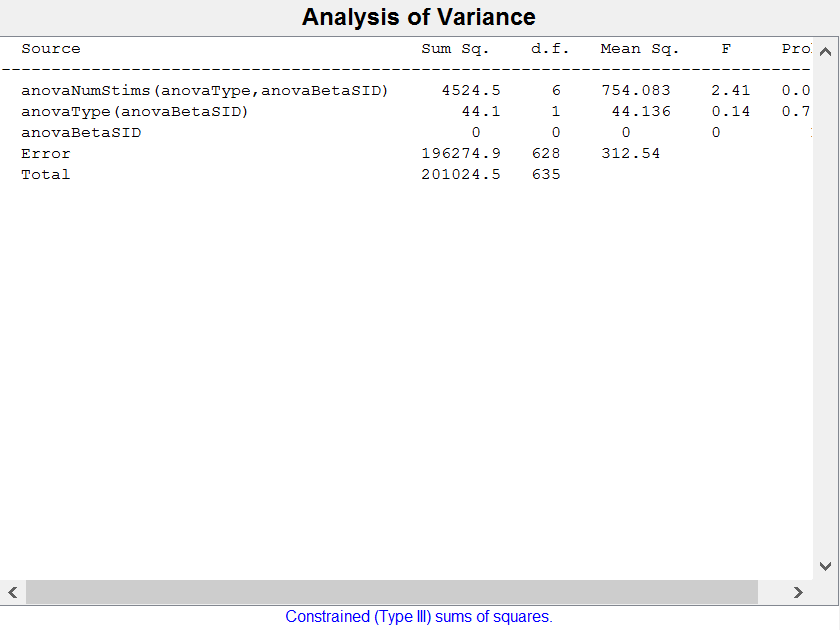

figure
[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'},'model','interaction','nested',[0 1 1;0 0 1;0 0 0],'sstype',3)

p =     0.3996
       NaN


tbl =     'Source'                     'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'    'F'         'Prob>F'
    'anovaType(anovaBetaSID)'    [  225.0604]    [   1]    [        0]    [225.0604]    [0.7106]    [0.3996]
    'anovaBetaSID'               [         0]    [   0]    [        0]    [       0]    [     0]    [   NaN]
    'Error'                      [2.0080e+05]    [ 634]    [        0]    [316.7183]          []          []
    'Total'                      [2.0102e+05]    [ 635]    [        0]            []          []          []


stats =          source: 'anovan'
          resid: [636x1 double]
         coeffs: [4x1 double]
            Rtr: [2x2 double]
       rowbasis: [2x4 double]
            dfe: 634
            mse: 316.7183
    nullproject: [4x2 double]
          terms: [2x2 double]
        nlevels: [2x1 double]
     continuous: [0 0]
         vmeans: [2x1 double]
       termcols: [3x1 double]
     coeffnames: {4x1 cell}
           vars: [4x2 double]
       varnames: {2x1 cell}
       grpnames: {2x1 cell}
        vnested: [2x2 double]
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


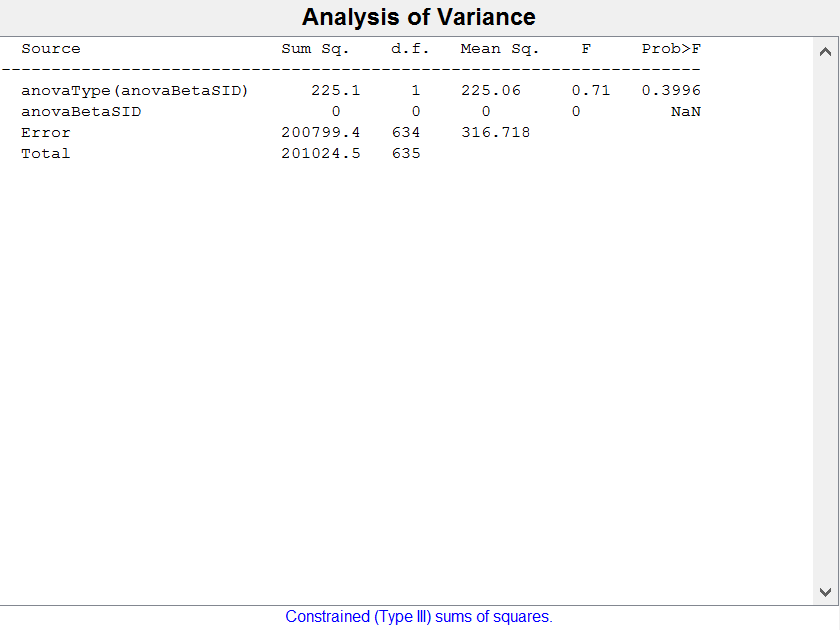

[p,tbl,stats] = anovan(anovaTotalMags,{anovaType,anovaBetaSID},'varnames',{'anovaType','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])

p =     0.0073
    0.7072
       NaN
    0.4676
       NaN
       NaN
       NaN


tbl =     'Source'                                  'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'      'F'         'Prob>F'
    'anovaNumStims'                           [3.7932e+03]    [   3]    [        0]    [1.2644e+03]    [4.0456]    [0.0073]
    'anovaType'                               [   44.1363]    [   1]    [        0]    [   44.1363]    [0.1412]    [0.7072]
    'anovaBetaSID'                            [         0]    [   0]    [        0]    [         0]    [     0]    [   NaN]
    'anovaNumStims*anovaType'                 [  795.6446]    [   3]    [        0]    [  265.2149]    [0.8486]    [0.4676]
    'anovaNumStims*anovaBetaSID'              [         0]    [   0]    [        0]    [         0]    [     0]    [   NaN]
    'anovaType*anovaBetaSID'                  [         0]    [   0]    [        0]    [         0]    [     0]    [   NaN]
    'anovaNumStims*anovaType*anovaBetaSID'    [         0]    [   0]    [        0]    [         0]    [     0]    [   NaN]
  

stats =          source: 'anovan'
          resid: [636x1 double]
         coeffs: [30x1 double]
            Rtr: [8x8 double]
       rowbasis: [8x30 double]
            dfe: 628
            mse: 312.5397
    nullproject: [30x8 double]
          terms: [7x3 double]
        nlevels: [3x1 double]
     continuous: [0 0 0]
         vmeans: [3x1 double]
       termcols: [8x1 double]
     coeffnames: {30x1 cell}
           vars: [30x3 double]
       varnames: {3x1 cell}
       grpnames: {3x1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


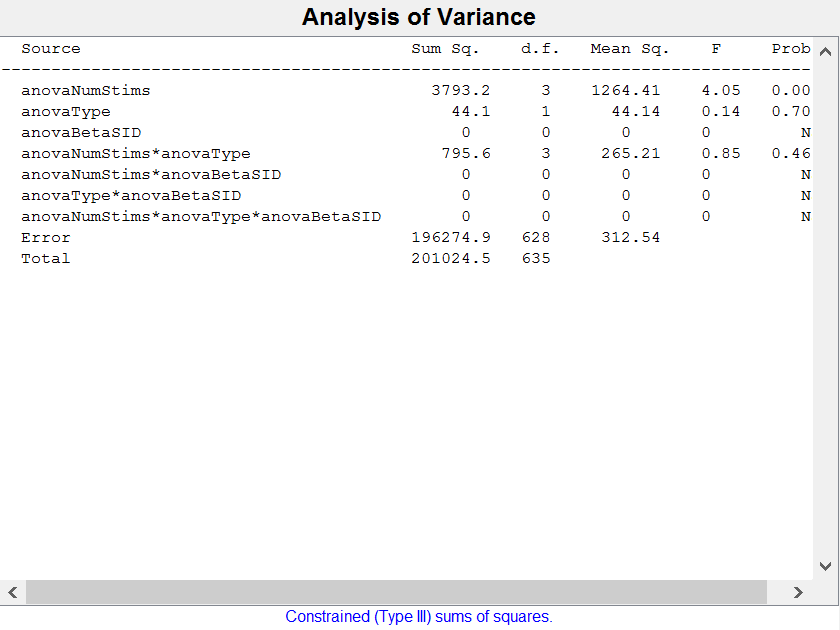

[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'model','full','varnames',{'anovaNumStims','anovaType','anovaBetaSID'})

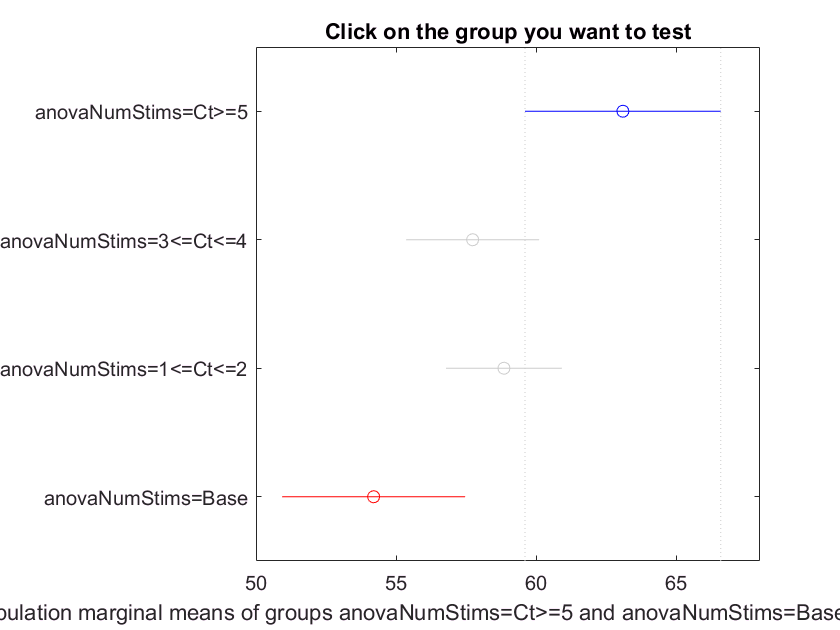

c =     1.0000    2.0000   -0.5402    5.3658   11.2718    0.0904
    1.0000    3.0000   -1.3611    4.2470    9.8552    0.2091
    1.0000    4.0000    2.2169    8.9015   15.5861    0.0035
    2.0000    3.0000   -5.4846   -1.1187    3.2471    0.9127
    2.0000    4.0000   -2.1470    3.5357    9.2184    0.3795
    3.0000    4.0000   -0.7181    4.6544   10.0270    0.1163


m =    63.1022    1.8924
   57.7364    1.3053
   58.8551    1.0882
   54.2007    1.7858


h =   Figure (16: Multiple comparison of population marginal means) with properties:

      Number: 16
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1.0003e+03 917.6667 560 420.0000]
       Units: 'pixels'

  Show all properties


gnames =     'anovaNumStims=Ct>=5'
    'anovaNumStims=3<=Ct<=4'
    'anovaNumStims=1<=Ct<=2'
    'anovaNumStims=Base'



%[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType},'varnames',{'anovaNumStims','anovaType'},'model','full

figure
[c,m,h,gnames] = multcompare(stats)

[gnames num2cell(m)]

ans =     'anovaNumStims=Ct>=5'       [63.1022]    [1.8924]
    'anovaNumStims=3<=Ct<=4'    [57.7364]    [1.3053]
    'anovaNumStims=1<=Ct<=2'    [58.8551]    [1.0882]
    'anovaNumStims=Base'        [54.2007]    [1.7858]


figure
% bar(m(:,1))
% hold on
errorbar((1:length(m(:,1))),flip(m(:,1)),flip(m(:,2)),'ro','linestyle','none','linew',2','color','r')
% xlabel('Patients and Task','fontsize',16,'fontweight','bold')
ylabel('Zscored CCEP Magnitude','fontsize',14,'fontweight','bold')
xlabel('Number of Conditioning Pulses','fontsize',14,'fontweight','bold')

ax = gca;
ax.XTickLabelMode = 'manual'

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [52 66]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1192 0.7750 0.8026]
            Units: 'normalized'

  Show all properties


ax.XTick = [1 2 3 4]

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [52 66]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1192 0.7750 0.8026]
            Units: 'normalized'

  Show all properties


ax.XTickLabel = {'Baseline','1->2','3->4','>5' }

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [52 66]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1192 0.7750 0.8026]
            Units: 'normalized'

  Show all properties


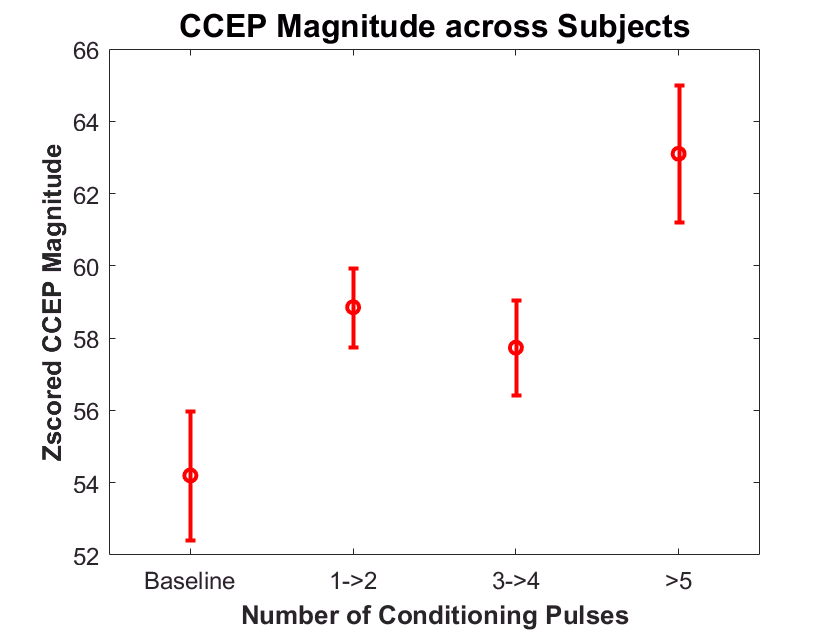

ax.FontSize = 12;
% ax.FontWeight = 'bold';
% set(gca,'XtickLabel',{'','>5','3->4', '1->2','Baseline'},'fontsize',14,'fontweight','bold')
title({'CCEP Magnitude across Subjects';},'fontsize',16,'fontweight','bold')

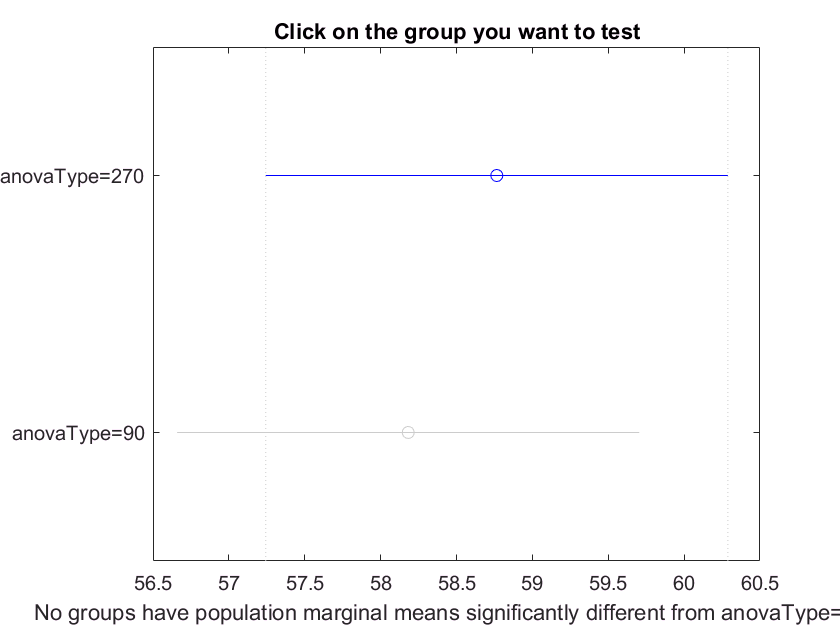

results1 =     1.0000    2.0000   -2.4616    0.5839    3.6295    0.7071



figure
results1 = multcompare(stats,'Dimension',[2])

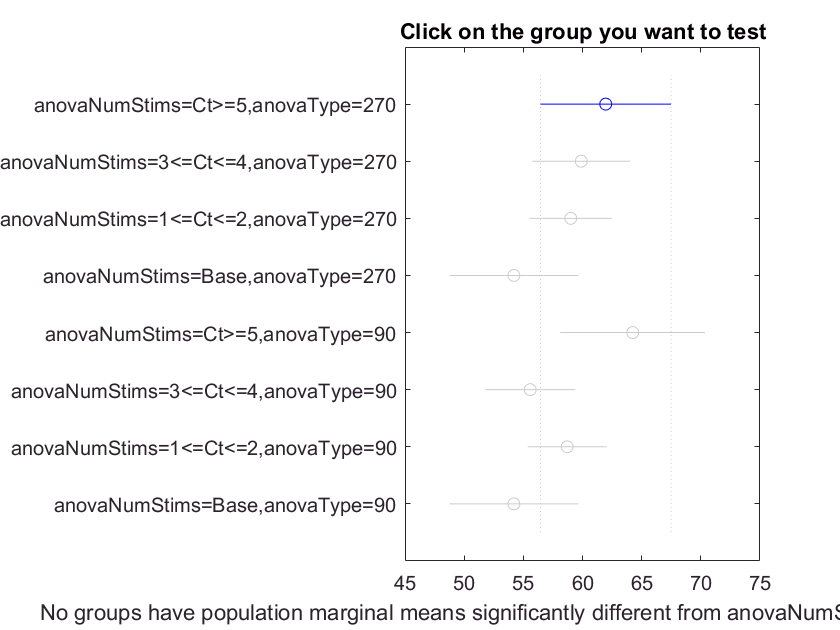

cM =     1.0000    2.0000   -7.6289    2.0661   11.7611    0.9982
    1.0000    3.0000   -6.1538    2.9549   12.0635    0.9769
    1.0000    4.0000   -3.1213    7.7602   18.6417    0.3754
    1.0000    5.0000  -13.7539   -2.2826    9.1886    0.9989
    1.0000    6.0000   -3.0108    6.3828   15.7765    0.4416
    1.0000    7.0000   -5.6975    3.2566   12.2107    0.9565
    1.0000    8.0000   -3.1213    7.7602   18.6417    0.3754
    2.0000    3.0000   -6.6831    0.8888    8.4606    1.0000
    2.0000    4.0000   -3.9378    5.6941   15.3259    0.6257
    2.0000    5.0000  -14.6422   -4.3487    5.9447    0.9063


mM =    61.9608    2.5517
   59.8947    1.9289
   59.0060    1.5876
   54.2007    2.5255
   64.2435    2.7953
   55.5780    1.7591
   58.7043    1.4888
   54.2007    2.5255


hM =   Figure (26: Multiple comparison of population marginal means) with properties:

      Number: 26
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1.0003e+03 917.6667 560 420.0000]
       Units: 'pixels'

  Show all properties


gnamesM =     'anovaNumStims=Ct>=5,anovaType=270'
    'anovaNumStims=3<=Ct<=4,anovaType=270'
    'anovaNumStims=1<=Ct<=2,anovaType=270'
    'anovaNumStims=Base,anovaType=270'
    'anovaNumStims=Ct>=5,anovaType=90'
    'anovaNumStims=3<=Ct<=4,anovaType=90'
    'anovaNumStims=1<=Ct<=2,anovaType=90'
    'anovaNumStims=Base,anovaType=90'




% figure
% results = multcompare(stats,'Dimension',[3])

figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 2])

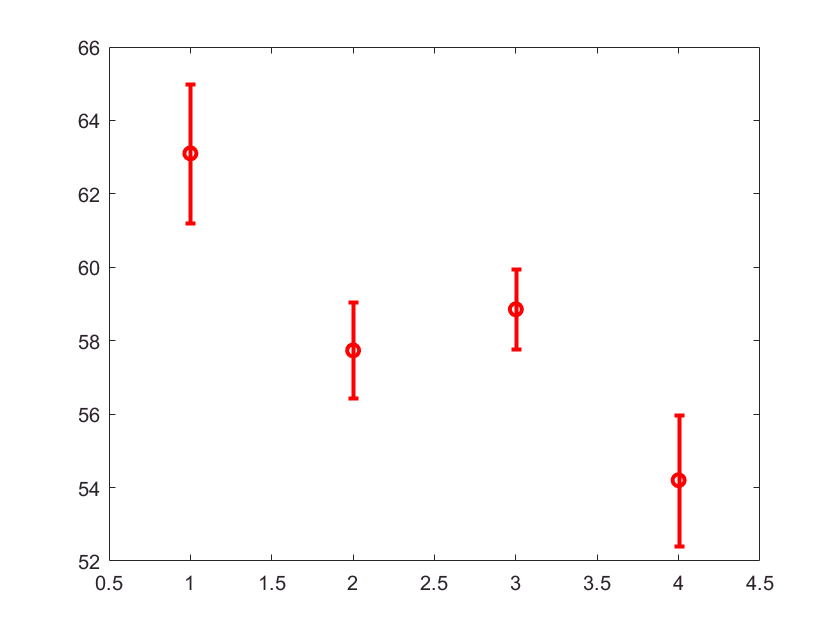



errorbar((1:length(m(:,1))),m(:,1),m(:,2),'ro','linestyle','none','linew',2','color','r')


figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[2 3])

Error using multcompare (line 245)
DIM must specify only categorical factors with 2 or more degrees of freedom.




figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 3])

p = 0.0074

tbl =     'Source'    'SS'            'df'     'MS'            'F'         'Prob>F'
    'Groups'    [3.7753e+03]    [  3]    [1.2584e+03]    [4.0321]    [0.0074]
    'Error'     [1.9725e+05]    [632]    [  312.1031]          []          []
    'Total'     [2.0102e+05]    [635]              []          []          []


stats =     gnames: {4x1 cell}
         n: [88 185 265 98]
    source: 'anova1'
     means: [62.9984 57.5380 58.8454 54.2007]
        df: 632
         s: 17.6664


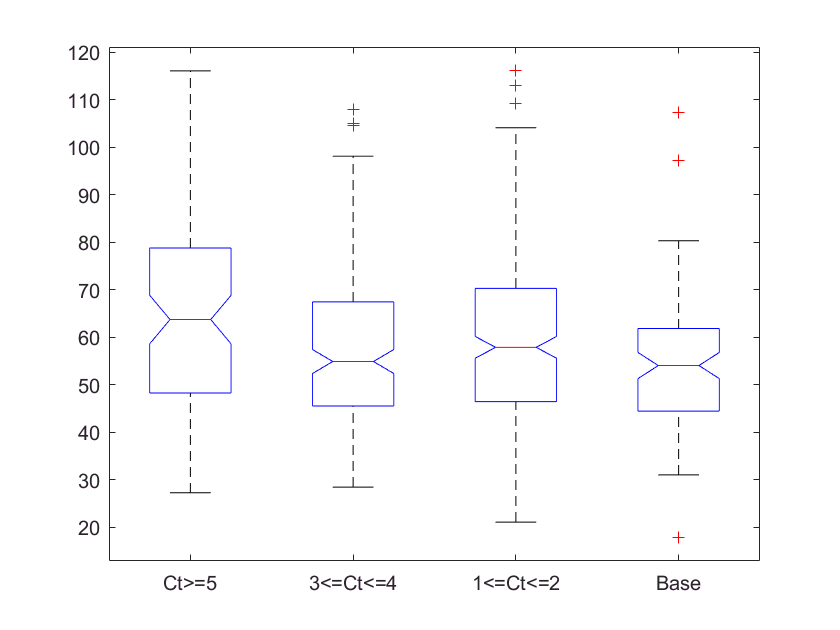

[p,tbl,stats] = anova1(anovaTotalMags,anovaNumStims)

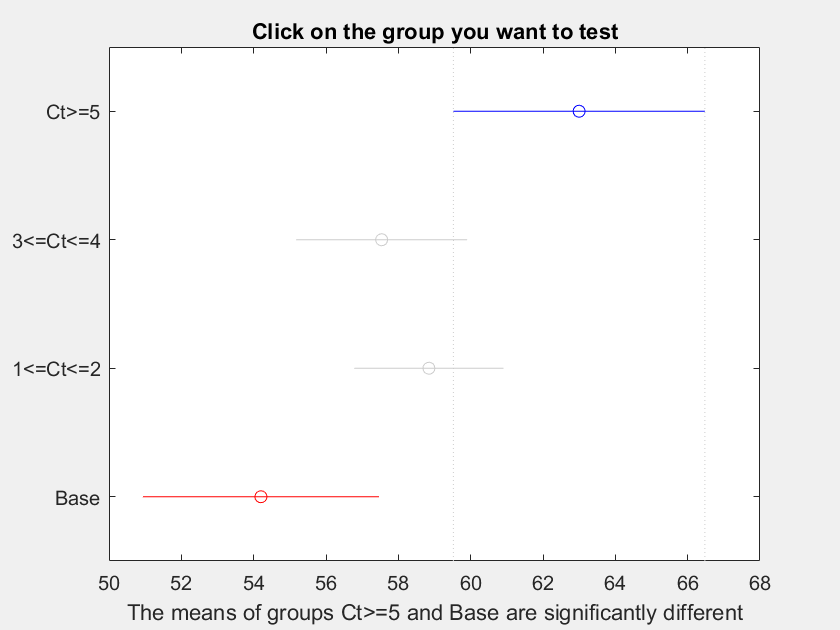

ans =     1.0000    2.0000   -0.4169    5.4604   11.3376    0.0796
    1.0000    3.0000   -1.4310    4.1530    9.7369    0.2235
    1.0000    4.0000    2.1324    8.7977   15.4630    0.0039
    2.0000    3.0000   -5.6557   -1.3074    3.0409    0.8669
    2.0000    4.0000   -2.3330    3.3374    9.0077    0.4302
    3.0000    4.0000   -0.7210    4.6448   10.0106    0.1168


multcompare(stats)